% H_infinity weight optimisers 
s = tf('s');  % Laplace variable

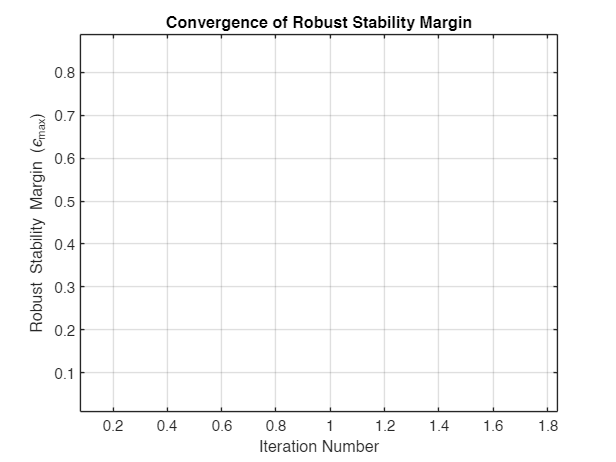

u_scale = 10^(20/20);
upper_bound = u_scale*250 / (s/2 + 1.5)^3; % TRIAL 1: THIS AND LB_2ND_ORDER WORKS
lower_bound = 15 / (s/2 + 1.5)^3;
% upper_bound = (700 * (s/2 + 1)^4) / ((s/0.2 + 1)^5 * (s/200 + 1)^5);
% lower_bound = (500 * (s/0.3 + 1)) / ((s/0.03 + 1)^2 * (s/30 + 1)^7);

K_lp = 0.1;
omega_n = 5;
zeta = 0.9;  % damping ratio
% lower_bound= K_lp * omega_n^2 / (s^2 + 2*zeta * omega_n * s + omega_n^2);  % 2nd order lower bound
% lower_bound = ss(10^(-80/20));


bounds = [upper_bound; lower_bound];
hold off

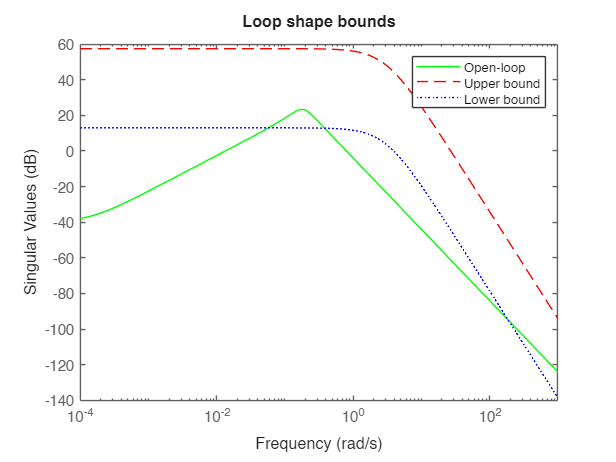

figure;
sigma(P_pitch, 'g', upper_bound, 'r--', lower_bound, 'b:', {1e-4, 1e3});
title("Loop shape bounds")
legend("Open-loop", "Upper bound", "Lower bound")



% hold off
% sigma(P_roll_cyc, 'g', upper_bound, 'r--', lower_bound, 'b:');
% title("Loop shape bounds")
% legend("Open-loop", "Upper bound", "Lower bound")

% [emax_pitch, W1_pitch, W2_pitch, Cinf_pitch] = optimise_compensators(P_pitch, bounds)
% [emax_lat, W1_lat, W2_lat, Cinf_lat] = optimise_compensators(P_pitch, bounds)


